mpm addpath

mpm: Adding cxro-intern-imaging-utils to MATLAB path


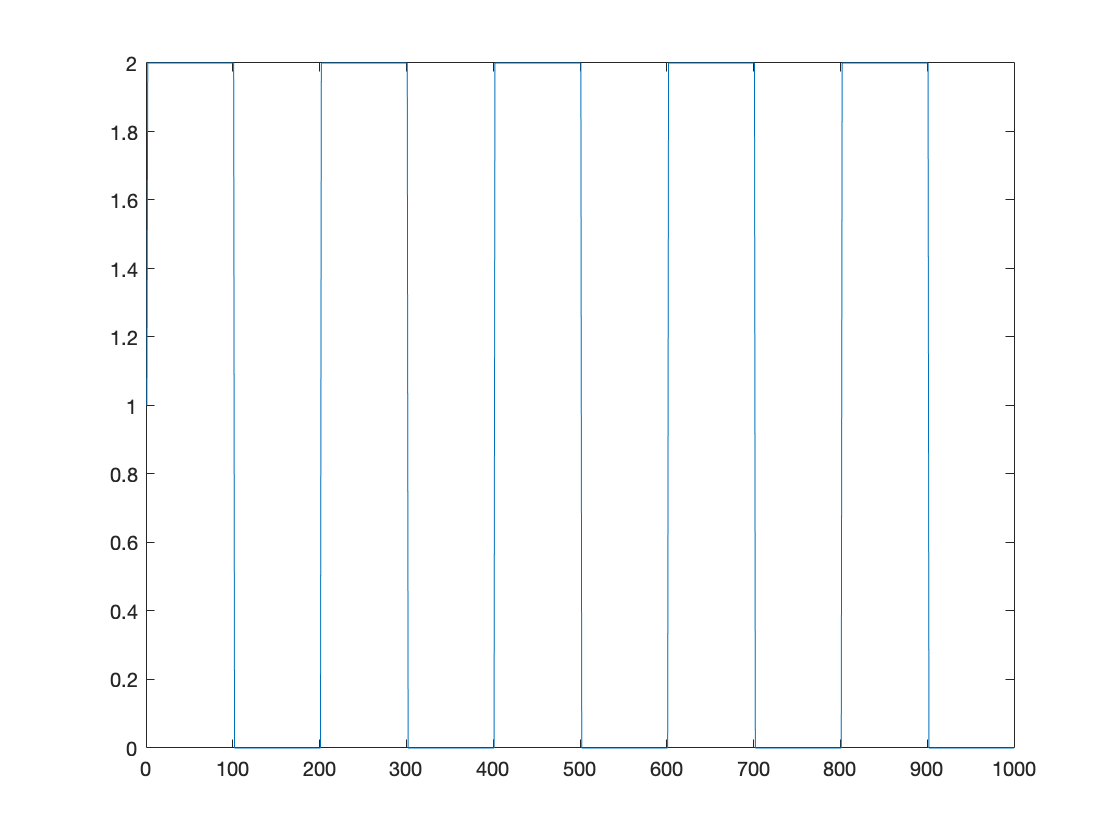

% 1D image modeling
idx = linspace(0, 10*pi, 1001);
idx = idx(1:end-1);

D = 100;

a = sign(sin(idx)) + 1;
NA = 3.01*6.7500e-04;

plot(a)

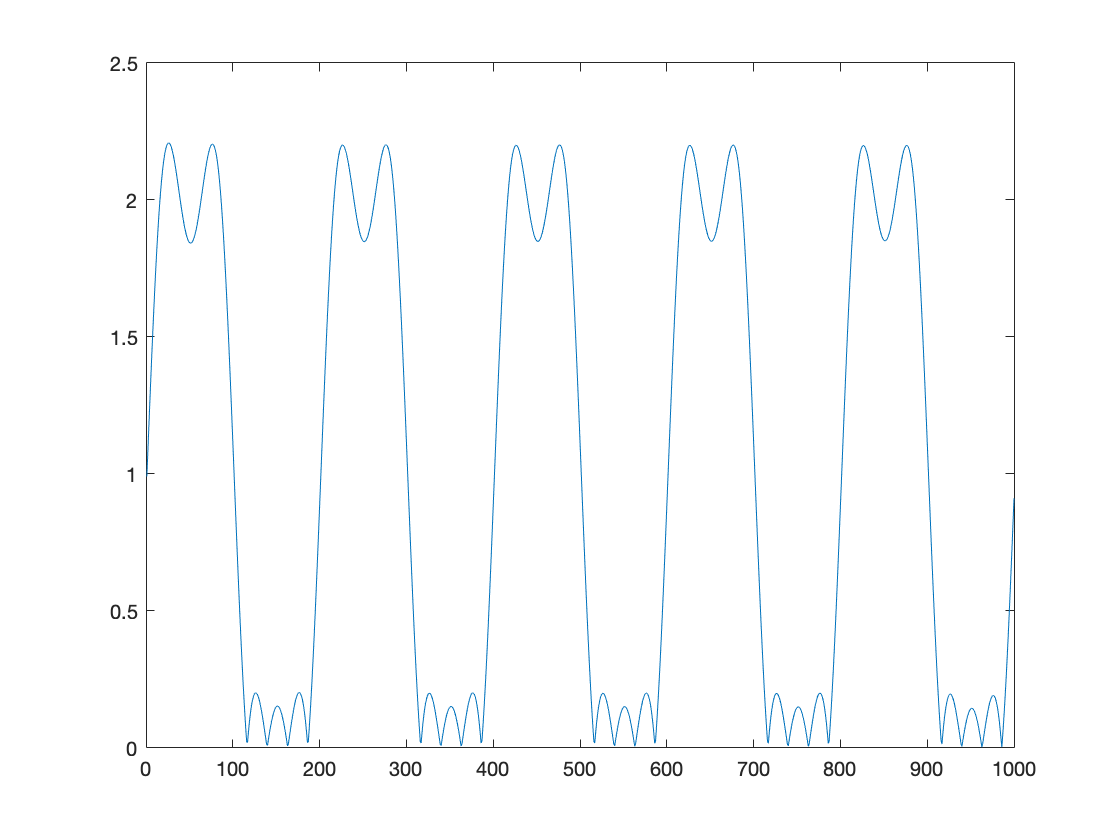

plot(abs(imageSim(a, D, .0135, NA)))

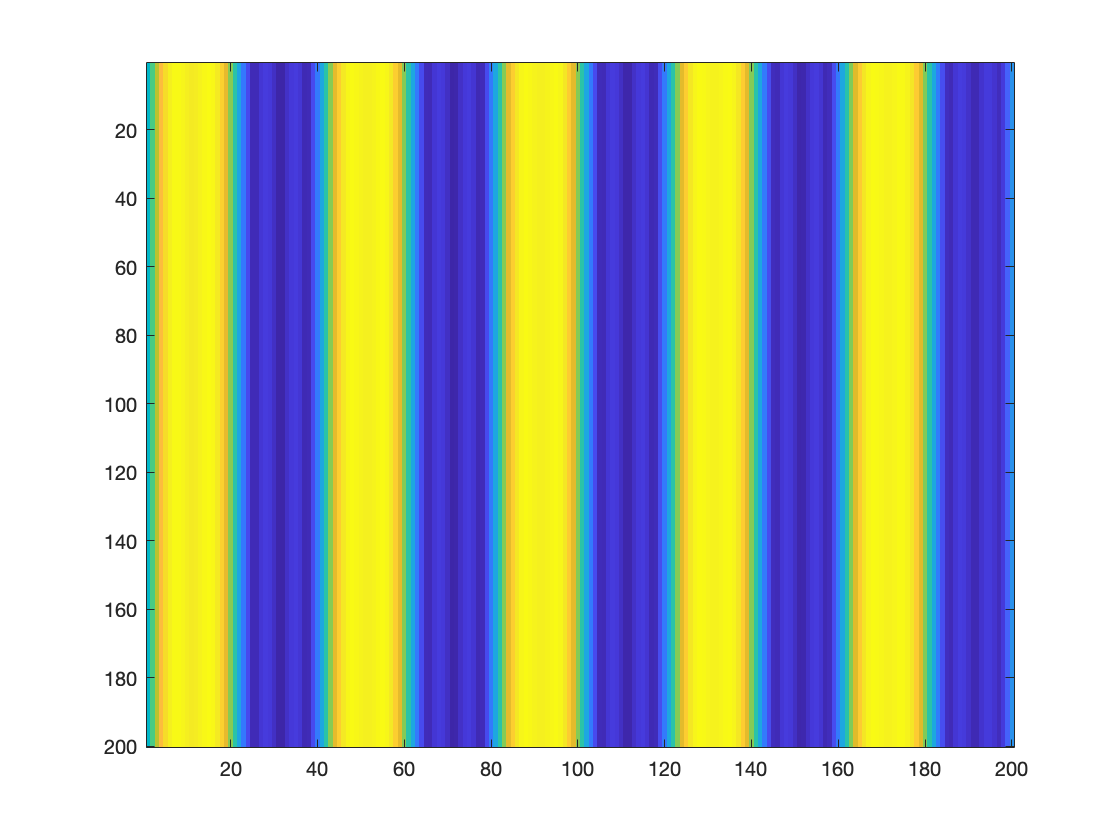

% 2D image modeling

idx = linspace(0, 10*pi, 201);
idx = idx(1:end-1);

D = [100, 100];

a = sign(sin(idx)) + 1;

% Extrude to 2 dimensions
A = ones(size(idx))'* a;

NA = 3.01*6.7500e-04;


imagesc(abs(imageSim(A, D, .0135, NA)))